# HW03

## Problem 4:

## Behavior of $\theta(t)$after a long time for different initial conditions:

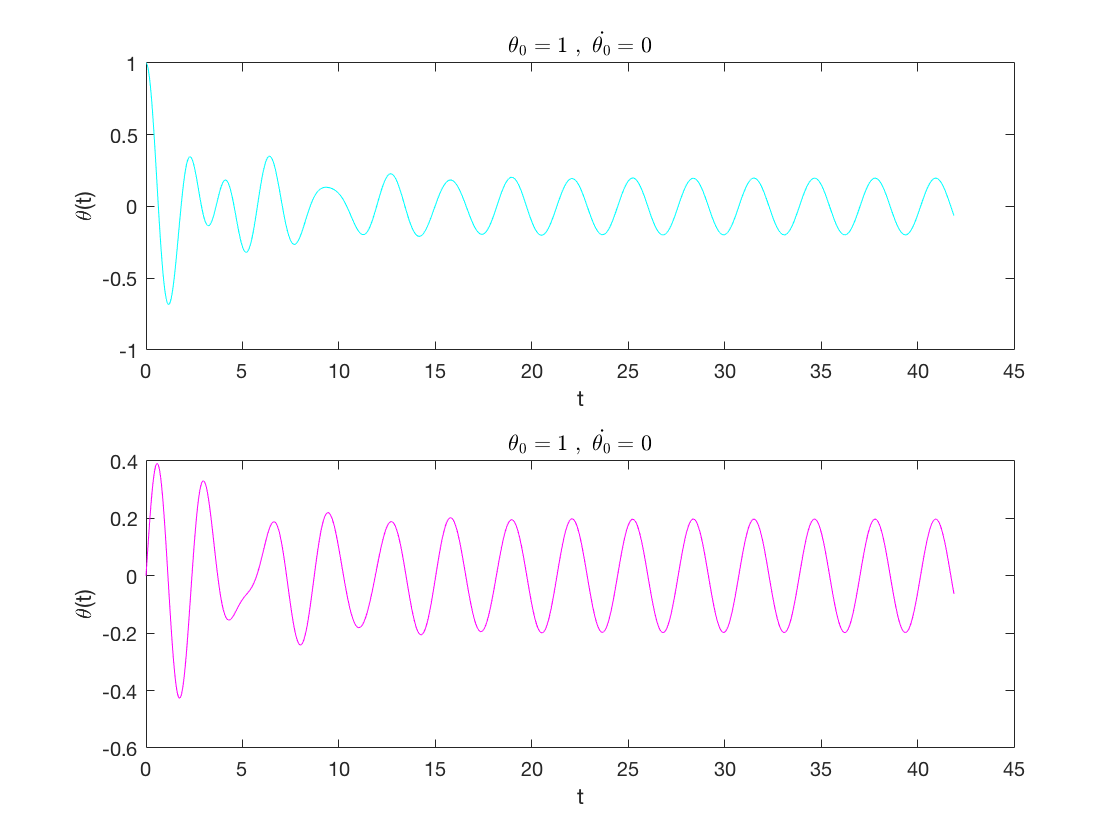

[T1,sol1]=forced_pendulum(1.09, 1,0,0,0.5,2);

[T2,sol2]=forced_pendulum(1.09, 0,1,0,0.5,2);

f1=figure;

subplot(2,1,1)
plot (sol1(:,1),sol1(:,2), 'c');
title('$\theta_0=1 \ , \ \dot{\theta_0}=0$', 'Interpreter','latex')
xlabel('t')
ylabel('\theta(t)')


subplot(2,1,2)
plot (sol2(:,1),sol2(:,2), 'm');
title('$\theta_0=1 \ , \ \dot{\theta_0}=0$', 'Interpreter','latex')
xlabel('t')
ylabel('\theta(t)')



fprintf('******************************** \n T1 = %f , w = %f  \n T2 = %f , w = %f \n******************************** ' , T1,6.28 ./ T1,T2 , 6.28 ./ T2);

******************************** 
 T1 = 2.910323 , w = 2.157836  
 T2 = 2.908150 , w = 2.159449 
******************************** 

## Behavior of $\theta(t)$ for different frequency of the external force :

frequency $\omega$ determines the period of the steady state.

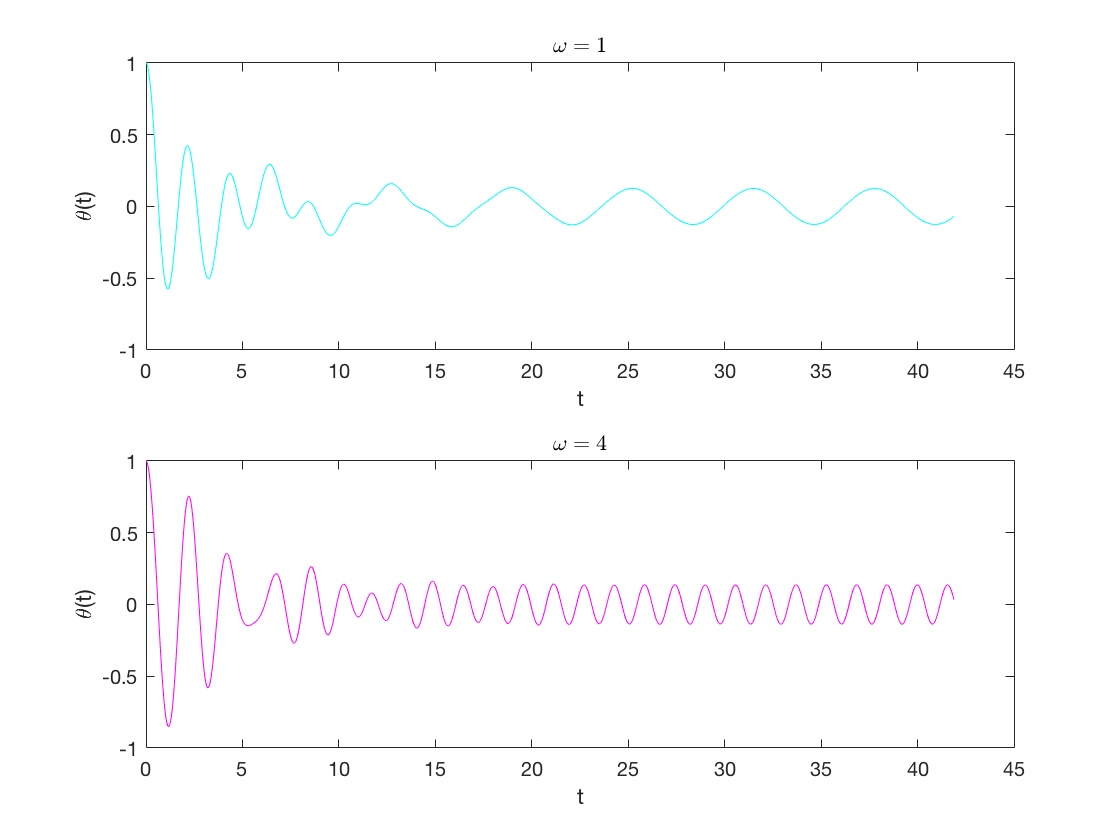

[T1,sol1]=forced_pendulum(1.09, 1,0,0,0.5,1);
[T2,sol2]=forced_pendulum(1.09, 1,0,0,0.5,4);

f2=figure;

subplot(2,1,1)
plot (sol1(:,1),sol1(:,2), 'c');
title('$\omega = 1$', 'Interpreter','latex')
xlabel('t')
ylabel('\theta(t)')


subplot(2,1,2)
plot (sol2(:,1),sol2(:,2), 'm');
title('$\omega =4$', 'Interpreter','latex')
xlabel('t')
ylabel('\theta(t)')



fprintf('******************************** \n T1 = %f , w = %f  \n T2 = %f , w = %f \n******************************** ' , T1,6.28 ./ T1,T2 , 6.28 ./ T2);

******************************** 
 T1 = 5.433770 , w = 1.155735  
 T2 = 1.394756 , w = 4.502579 
******************************** 

## Verifying the following equation:


$$\theta(t) = A(\omega)\cos(\omega t + \delta) $$



$$\delta = \cos ^{-1}(\frac{\theta}{A})-\omega t$$


For $\omega=2$ we have :

clear max;
w=2 % frequency of the driven force

w = 2

[T,sol]=forced_pendulum(1.09, 1,0,0,0.5,2);
l=length(sol(:,1)) ;
l=int16(l/2);% using the second half of the data which represents the steady state
M=sol(end-l:end,2);
A =max(M); % amplitude
delta=acos(sol(end-l:end,2)/A)-w*mod((sol(end-l:end,1)),T) % phase shift

delta =   -2.9755 + 0.0000i
  -2.9714 + 0.0000i
  -2.9676 + 0.0000i
  -2.9640 + 0.0000i
  -2.9605 + 0.0000i
  -2.9571 + 0.0000i
  -2.9539 + 0.0000i
  -2.9508 + 0.0000i
  -2.9478 + 0.0000i
  -2.9449 + 0.0000i
  -2.9419 + 0.0000i
  -2.9383 + 0.0000i
  -2.9340 + 0.0000i
  -2.9284 + 0.0000i
  -2.9200 + 0.0000i
   2.9197 + 0.0000i
   2.9557 - 0.0920i
   2.8559 - 0.1208i
   2.7560 - 0.0258i
   2.4735 + 0.0000i
   2.2606 + 0.0000i
   2.0546 + 0.0000i
   1.8513 + 0.0000i
   1.6728 + 0.0000i
   1.4949 + 0.0000i
   1.3175 + 0.0000i
   1.1403 + 0.0000i
   0.9634 + 0.0000i
   0.7867 + 0.0000i
   0.5834 + 0.0000i
   0.3802 + 0.0000i
   0.1773 + 0.0000i
  -0.0254 + 0.0000i
  -0.2279 + 0.0000i
  -0.4303 + 0.0000i
  -0.6512 + 0.0000i
  -0.8719 + 0.0000i
  -1.0923 + 0.0000i
  -1.3121 + 0.0000i
  -1.5314 + 0.0000i
  -1.7501 + 0.0000i
  -1.9638 + 0.0000i
  -2.1764 + 0.0000i
  -2.3873 + 0.0000i
  -2.5953 + 0.0000i
  -2.7979 + 0.0000i
  -2.9897 + 0.0000i
  -3.1506 + 0.0000i
  -3.2677 + 0.0000i
  -3.3328 + 


delta=mean(delta)

delta =   -1.3246 - 0.0005i



y=A .* cos(w .* sol(:,1) + 6.28 *delta);

f3=figure;
plot(sol(:,1),y, 'k--', sol(:,1),sol(:,2),'g')

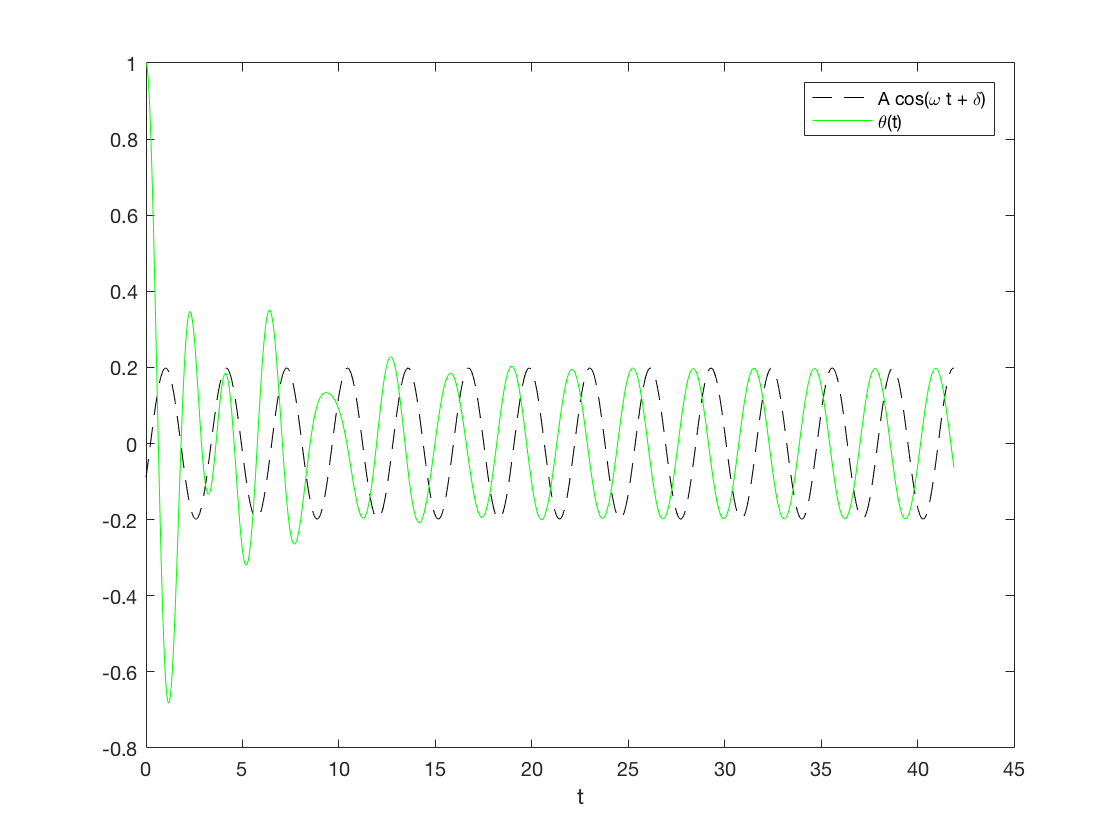

legend('A cos(\omega t + \delta) ','\theta(t)')
xlabel('t');

## Dependence of $\delta $on $\omega$:

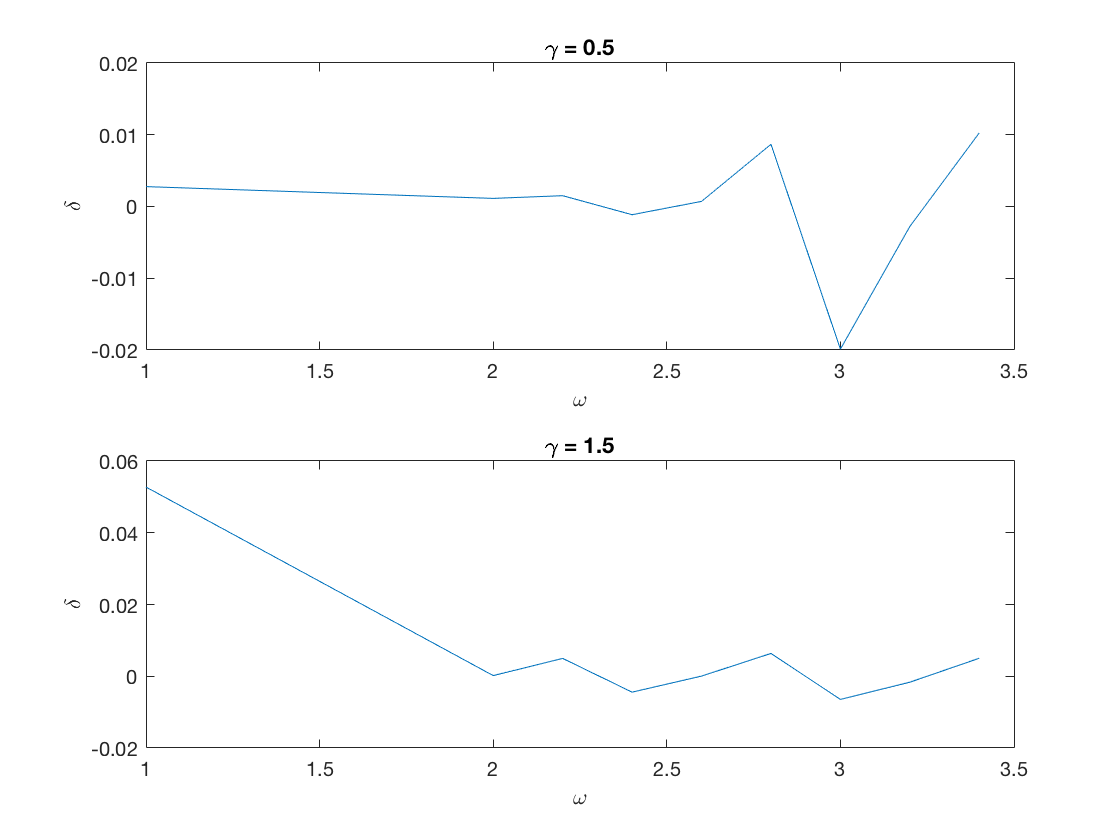

gamma=0.5; % damping coefficient
w=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
delta1=zeros(length(w),1);
for i=1:length(w)
   [T,sol]=forced_pendulum(1.09, 1,0,0,gamma,w(i)); 
   y = (1 ./ w(i)^2).* cos(w(i) .* sol(:,1));
   l=length(sol(:,1)) ;
   l=int16(l/2);% using the second half of the data which represents the steady state
   delta_array=sol(end-l:end,2)-y(end-l:end);
   delta1(i)=mean(delta_array);
   
end    

gamma=1.5; % damping coefficient
w=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
delta2=zeros(length(w),1);
for i=1:length(w)
   [T,sol]=forced_pendulum(1.09, 1,0,0,gamma,w(i)); 
   y = (1 ./ w(i)^2).* cos(w(i) .* sol(:,1));
   l=length(sol(:,1)) ;
   l=int16(l/2);% using the second half of the data which represents the steady state
   delta_array=sol(end-l:end,2)-y(end-l:end);
   delta2(i)=mean(delta_array);
   
end    

f4=figure;
subplot(2,1,1)
plot(w,delta1);
title('\gamma = 0.5')
xlabel('\omega');
ylabel('\delta');


subplot(2,1,2)
plot(w,delta2);
title('\gamma = 1.5')
xlabel('\omega');
ylabel('\delta');

## Resonance:

Maximum amplitude occures at $\omega_{max} <\omega_0=3$ for $\gamma=0.5$.

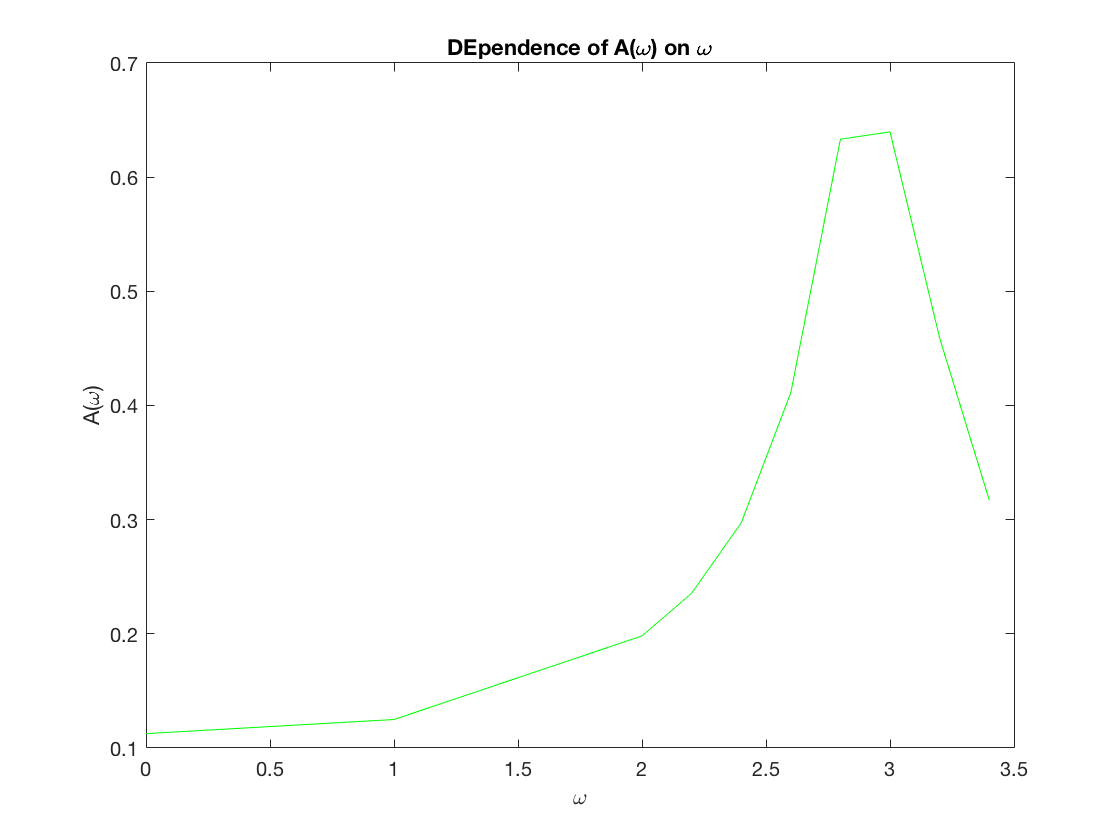

clear max;
gamma=0.5; % damping coefficient
w=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
A=zeros(length(w),1);
for i=1:length(w)
   [T,sol]=forced_pendulum(1.09, 0,0,0,gamma,w(i)); 
   l=length(sol(:,1)) ;
   l=int16(l/2);% using the second half of the data which represents the steady state
   M=sol(end-l:end,2);
   A(i) = max(M);
   
end    

f5=figure;
plot(w,A,'g');
title('DEpendence of A(\omega) on \omega');
xlabel('\omega');
ylabel('A(\omega)');

[Amax,ind]=max(A); 
wmax=w(ind);
ind1=0;
ind2=0;
for i=1:length(w)
    if A(i) <= (1 ./ sqrt(2)) * Amax && w(i) < wmax
        ind1=i;
    end
    
    if A(i) <= (1 ./ sqrt(2)) * Amax && w(i) > wmax
        ind2=i;
    end
end    

delta_w=w(ind2)-w(ind1);
fprintf('**************************** \n A_max = %f \n w_max = %f \n delta_w = %f \n****************************\n', Amax , wmax,delta_w);

**************************** 
 A_max = 0.639660 
 w_max = 3.000000 
 delta_w = 0.800000 
****************************


## Dependence of $A_{max}$ and $\frac{\Delta\omega}{\omega_{max}}$ on $\gamma$:

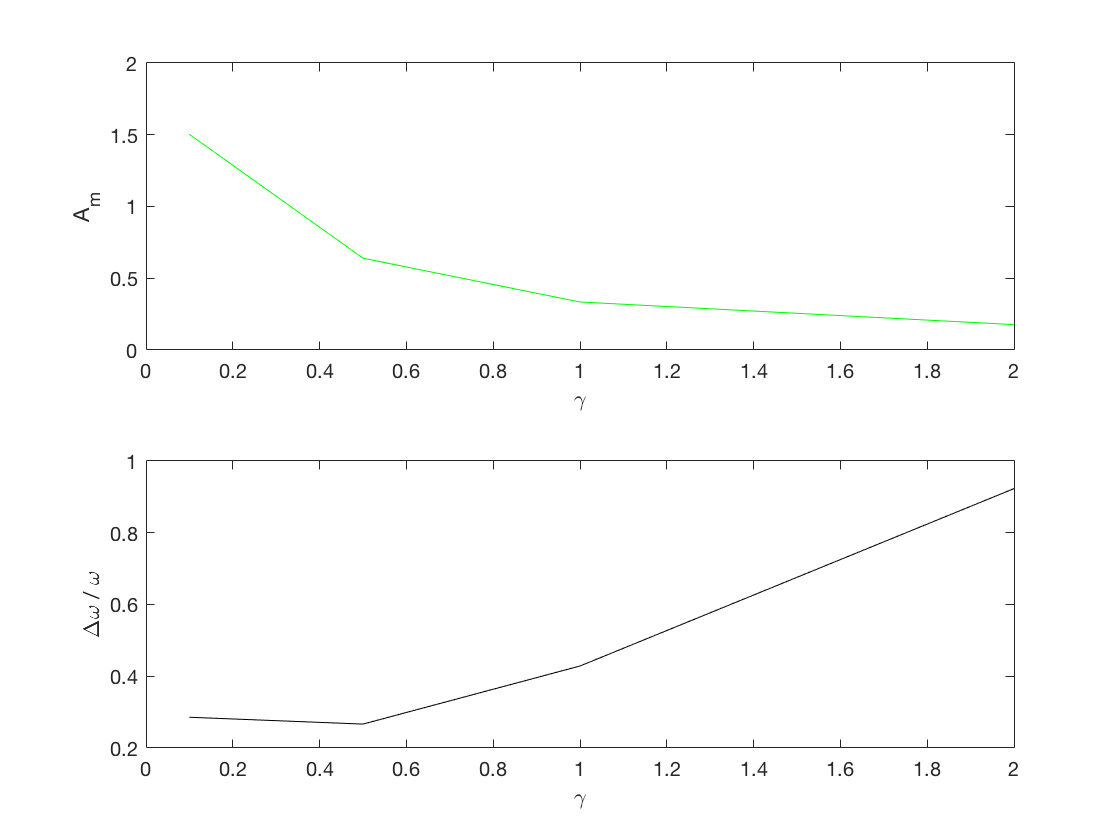

clear max;
gamma=[0.1, 0.5, 1.0, 2.0];
w=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
Amax=zeros(length(gamma),1);
wmax=zeros(length(gamma),1);
delta_w=zeros(length(gamma),1);

for j=1:length(gamma)
    A=zeros(length(w),1);
    for i=1:length(w)
        
        [T,sol]=forced_pendulum(1.09, 0,0,0,gamma(j),w(i)); 
        l=length(sol(:,1)) ;
        l=int16(l/2);% using the second half of the data which represents the steady state
        M=sol(end-l:end,2);
        A(i) = max(M);
      
    end    
     [Amax(j),ind]=max(A); 
      wmax(j)=w(ind);
      for k=1:length(w)
           if (A(k) <= (1 ./ sqrt(2)) * Amax(j)) && (w(k) < wmax(j))
               ind1=k;
           end
    
          if A(k) <= (1 ./ sqrt(2)) * Amax(j) && w(k) > wmax(j)
               ind2=k;
          end
      end    

     delta_w(j)=w(ind2)-w(ind1);
     
    
       
end   

ratio=delta_w ./ wmax;
f6=figure;
subplot(2,1,1)
plot(gamma,Amax,'g')
xlabel('\gamma')
ylabel('A_m')

subplot(2,1,2)
plot(gamma,ratio,'k')
xlabel('\gamma')
ylabel('\Delta\omega / \omega')